**S(15 marks) Consider a one-step adaptive predictor for a generic second order real AR process defined by the  difference equation u(n) + a1 u(n-1) +a2 u(n-2) = v(n), where v(n) is a zero-mean white noise process with  variance, 𝜎^2 . **

**a. Derive the equations for r(0), r(1), and r(2). **

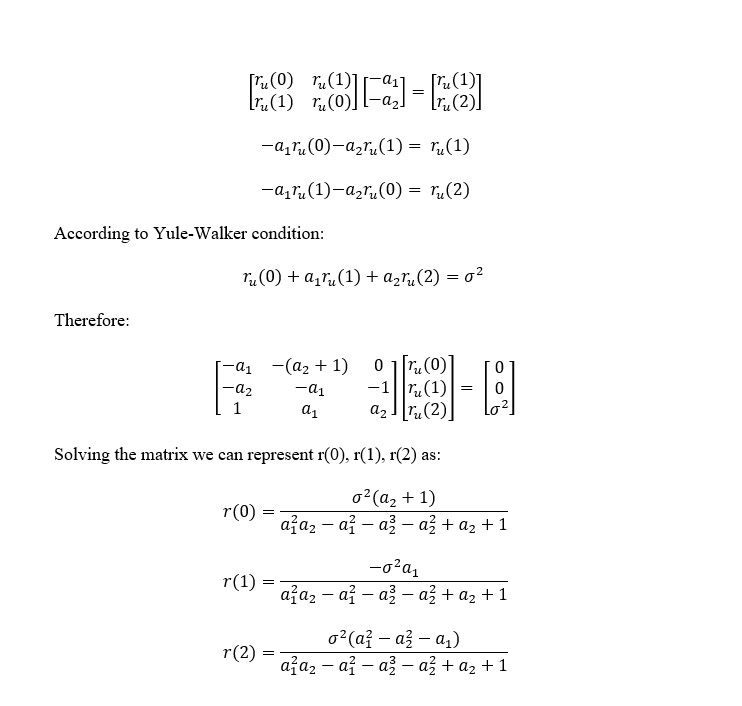

**b. If a1 = -1.9, a2 = 0.95, and 𝜎^2 = 1, compute the eigenvalues, eigenvectors, and the eigenvalue spread in  MATLAB.**

r0 = 202.597402597; %  r(0)
r1 = 197.402597403; % r(1)


R = [r0, r1 ; r1, r0];

% Compute eigenvalues and eigenvectors
[eigen_vector, D] = eig(R);

eigen_values = diag(D);

% Calculate eigenvalue spread
eigen_spread = max(eigen_values) / min(eigen_values);

disp('Eigenvalues:');

Eigenvalues:


disp(eigen_values);

    5.1948
  400.0000




disp('Eigenvectors:');

Eigenvectors:


disp(eigen_vector);

   -0.7071    0.7071
    0.7071    0.7071




disp('Eigenvalue spread:');

Eigenvalue spread:


disp(eigen_spread);

   77.0000



**c. Define 𝑒(𝑛) = 𝑢(𝑛) − 𝑢̑(𝑛), 𝜀1 (𝑛) = 1.9 − 𝑤1 (𝑛), and 𝜀2 (𝑛) = −0.95 − 𝑤2(𝑛). Using the LMS  algorithm with the convergence parameter, mu = 0.003, plot the power spectral densities for e(n),  𝜀1(𝑛), and 𝜀2(𝑛). Include these plots in your assignment, clearly labeling the axes. What observations  can you make from these plots? **

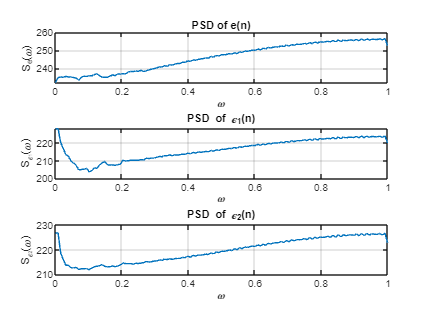

a1 = -1.9; a2 = 0.95;  N = 1000;
mu = 0.003; % Convergence parameter

% Generate AR process signal u(n)
v = randn(N,1); % White noise process
u = filter(1, [1 a1 a2], v);  %using A(z) to get AR model

% Initialize LMS algorithm parameters
w1 = zeros(N,1); 
w2 = zeros(N,1); % Weight initialization
e = zeros(N,1); % Error initialization

% LMS algorithm / the current value becomes d(n) / one-step prediction
for n =3:length(v)
    u_est_lms = conj(w1(n))*u(n-1) + conj(w2(n))*u(n-2); % estimated (reference value)/ use the past value from u(n-1)*w1 to u(n-2)*w2.
    e(n) = u(n) - u_est_lms; % Error is the differenct between d(n) (u(n)) and u(n-1) estimated value
    % Update weights
    w1(n+1) = w1(n) + mu*u(n-1)*conj(e(n));
    w2(n+1) = w2(n) + mu*u(n-2)*conj(e(n));   
end

epsilon1 = 1.9 - w1;
epsilon2 = -0.95 - w2;

figure;
% Power spectral density of e(n)
subplot(3,1,1);
pwelch(e,'psd');
title('PSD of e(n)');
xlabel('\omega');ylabel('S_e(\omega)');

% Power spectral density of epsilon1
subplot(3,1,2);
pwelch(epsilon1,'psd');
title('PSD of \epsilon_1(n)');
xlabel('\omega');ylabel('S_{\epsilon_1}(\omega)');

% Power spectral density of epsilon2
subplot(3,1,3);
pwelch(epsilon2,'psd');
title('PSD of \epsilon_2(n)');
xlabel('\omega');ylabel('S_{\epsilon_2}(\omega)');

**d. Compute the ensemble-average learning curves for the NLMS algorithm using mu = 0.05. Include these plots with your assignment, along with your observations comparing the NLMS and LMS results.**

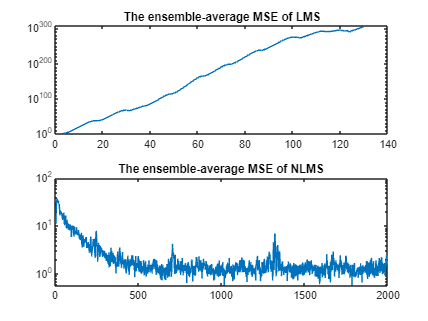

mu_lms=0.05;
mu_nlms=0.05;
N=2000;
a1 = -1.9; 
a2 = 0.95;  

e_ensemble=zeros(1,N);
e_ensemble_nlms=zeros(1,N);

for j=1:50

    %generate the stepped noise
    v = randn(1,N); % White noise process
    u = filter(1, [1 a1 a2], v);  %using A(z) to get AR model

    %initialization
    lms_weights_1=zeros(1,length(u));
    lms_weights_2=zeros(1,length(u));
    nlms_weights_1=zeros(1,length(u));
    nlms_weights_2=zeros(1,length(u));
    e = zeros(1, length(u)); % Error for LMS
    e_nlms = zeros(1, length(u)); % Error for NLMS
    mu = zeros(1, length(u)); % Adaptive step size for NLMS

    for i=3:length(u)-1

        %% NLMS %%
        u_est_nlms = conj(nlms_weights_1(i))*u(i-1) + conj(nlms_weights_2(i))*u(i-2);
        e_nlms(i) = u(i) - u_est_nlms;
        nlms_weights_1(i+1) = nlms_weights_1(i) + mu_nlms*u(i-1)*conj(e_nlms(i))/(0.001 + abs(u(i-1))^2 + abs(u(i-2))^2);
        nlms_weights_2(i+1) = nlms_weights_2(i) + mu_nlms*u(i-1)*conj(e_nlms(i))/(0.001 + abs(u(i-1))^2 + abs(u(i-2))^2);
        
        %% LMS %%
        u_est_lms = conj(lms_weights_1(i))*u(i-1) + conj(lms_weights_2(i))*u(i-2);
        e(i) = u(i) - u_est_lms;
        lms_weights_1(i+1) = lms_weights_1(i) + mu_lms*u(i-1)*conj(e(i));
        lms_weights_2(i+1) = lms_weights_2(i) + mu_lms*u(i-1)*conj(e(i));
        
    end;
    
    e_ensemble = e_ensemble + e.^2;
    e_ensemble_nlms = e_ensemble_nlms + e_nlms.^2;
end;

e_ensemble = e_ensemble/50;
e_ensemble_nlms = e_ensemble_nlms/50;

% Plotting
figure;
subplot(211); 
semilogy(1:length(e), e_ensemble); 
title('The ensemble-average MSE of LMS');
subplot(212); 
semilogy(1:length(e_nlms), e_ensemble_nlms); 
title('The ensemble-average MSE of NLMS');